## TF 2kV 真空磁場

### 全chオシロ波形

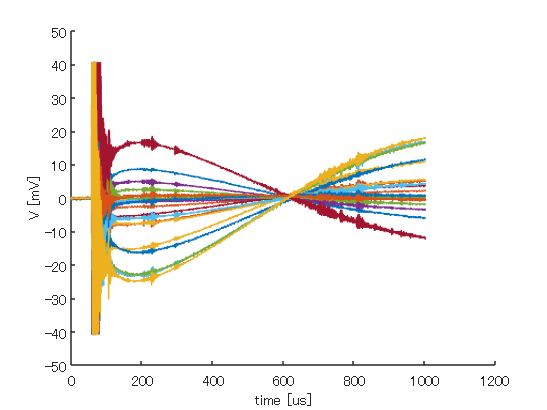

experiment_date = '230114';
data_directory = strcat('C:\Users\uswk0\OneDrive\ドキュメント\GitHub\test-open\道家\卒論\data\',experiment_date);


filename = 'toroidal_mode20230114_101911_No1.csv'; %TF2kV
%filename = 'toroidal_mode20230114_105719_No4.csv';
%filename = 'toroidal_mode20230114_105225_No3.csv'; %PF20kV
%filename = 'toroidal_mode20230114_114006_No6.csv';
%filename = 'toroidal_mode20230114_124327_No7.csv';
file_path = strcat(data_directory, '\', filename); 

M = readmatrix(file_path);
%disp(M);
t = M(:,1);

figure;
hold on;
plot(t, M(:,2:25)*10^3);
%legend('ch1','ch2','ch3','ch4','ch5','ch6','ch7','ch8','ch9','ch10','ch11','ch12','ch13','ch14','ch15','ch16','ch17','ch18','ch19','ch20','ch21','ch22','ch23','ch24');
xlim();
ylim();
xlabel('time [us]');
ylabel('V [mV]');
%title('TF39kV shot');
hold off;

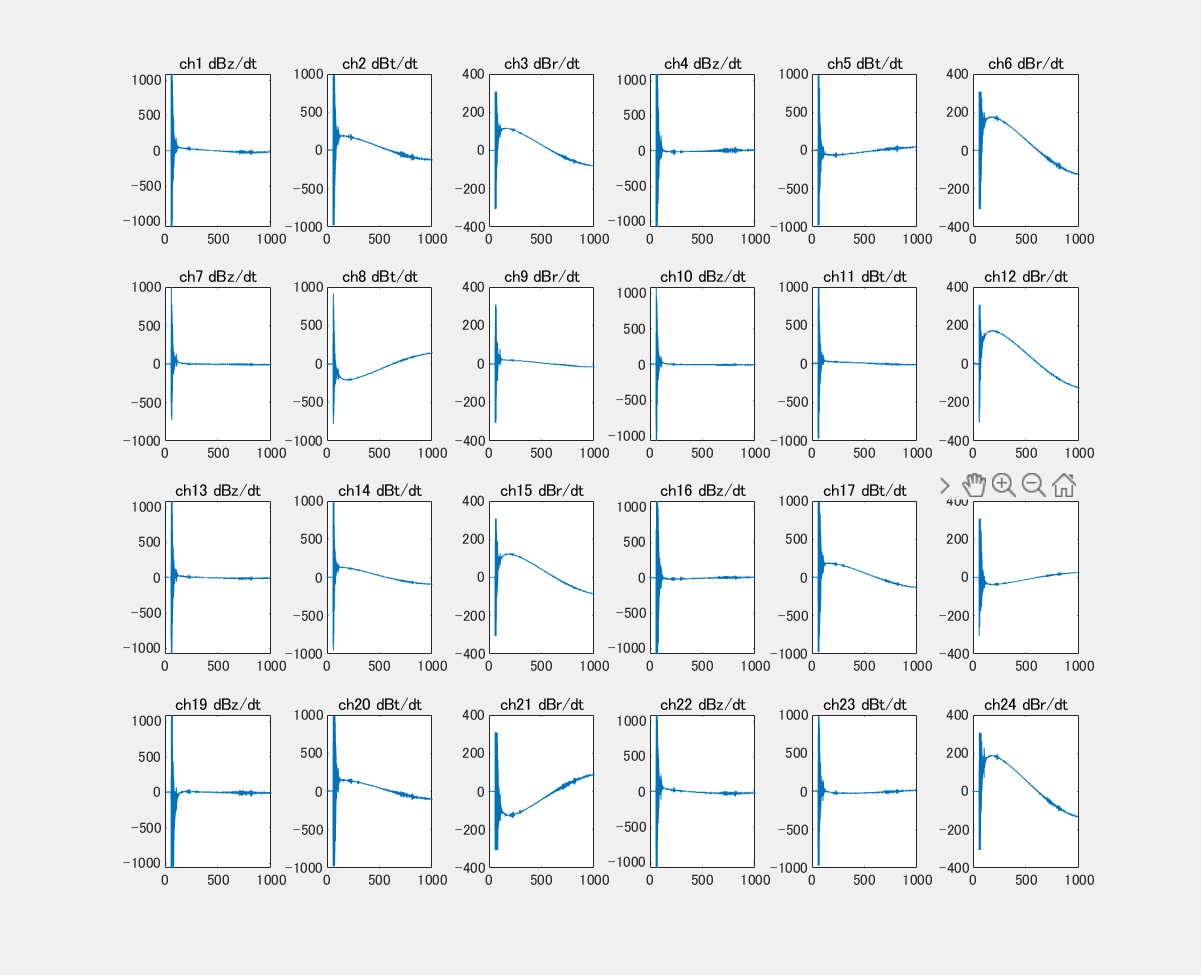


figure('Position', [0 0 800 800],'visible','on');
%較正係数(NSbz, NSbt, NSbr)
NSztr = [37.7, 41.6,133]*10^-6;

for i =1:24
    subplot(4,6,i);
 
    if rem(i,3) == 1
        plot(t, -M(:,i+1)/NSztr(1));
        title(strcat('ch',num2str(i),' dBz/dt'));
    elseif rem(i,3) == 2
        plot(t, -M(:,i+1)/NSztr(2));
         title(strcat('ch',num2str(i),' dBt/dt'));
    else
         plot(t, -M(:,i+1)/NSztr(3));
         title(strcat('ch',num2str(i),' dBr/dt'));
    end
end

### 各プローブごと (dBz/dt, dBt/dt, dBr/dt) 

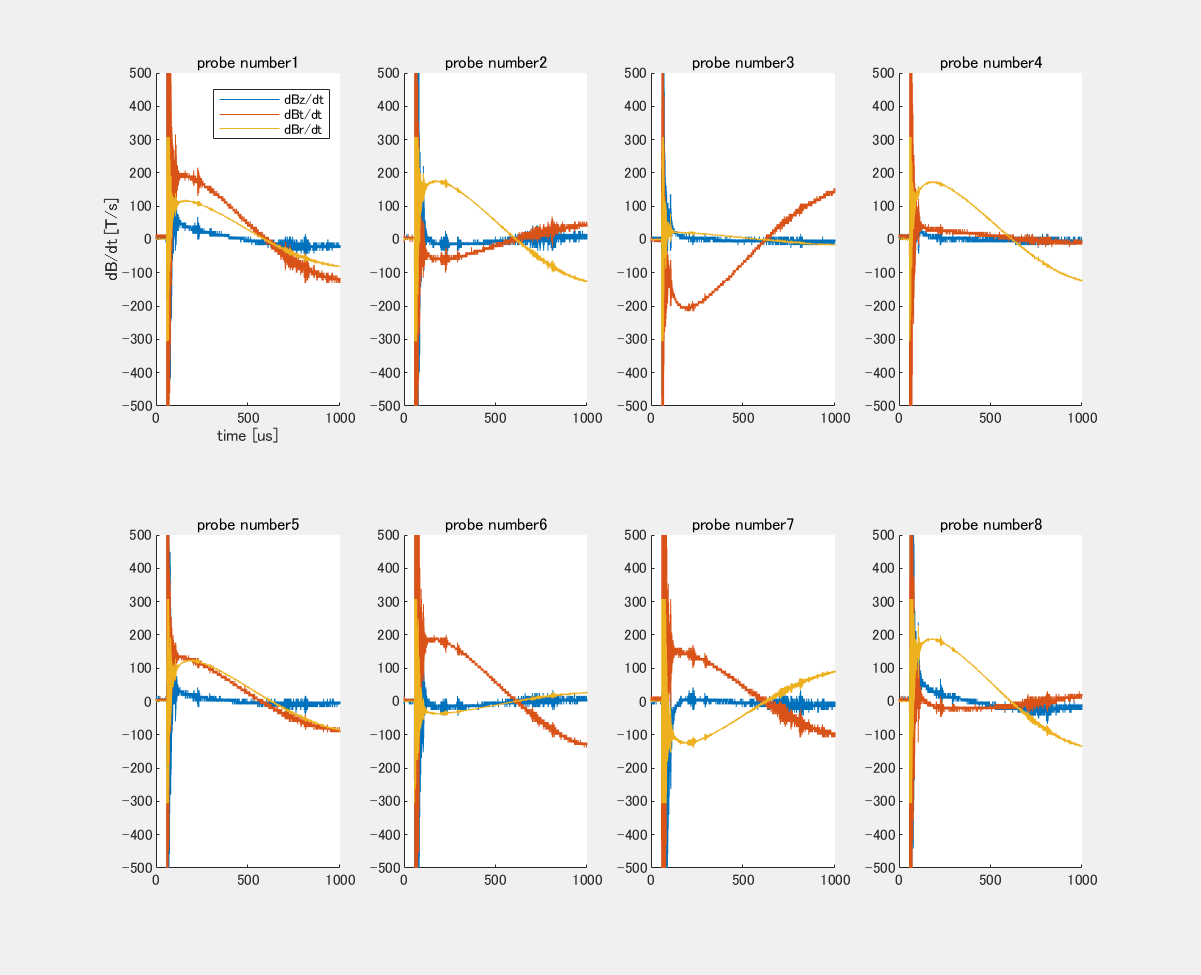

%それぞれのプローブごとに(bz, bt, br)を表示
 plot_each_probe(M, 8);

## すべてのchの信号

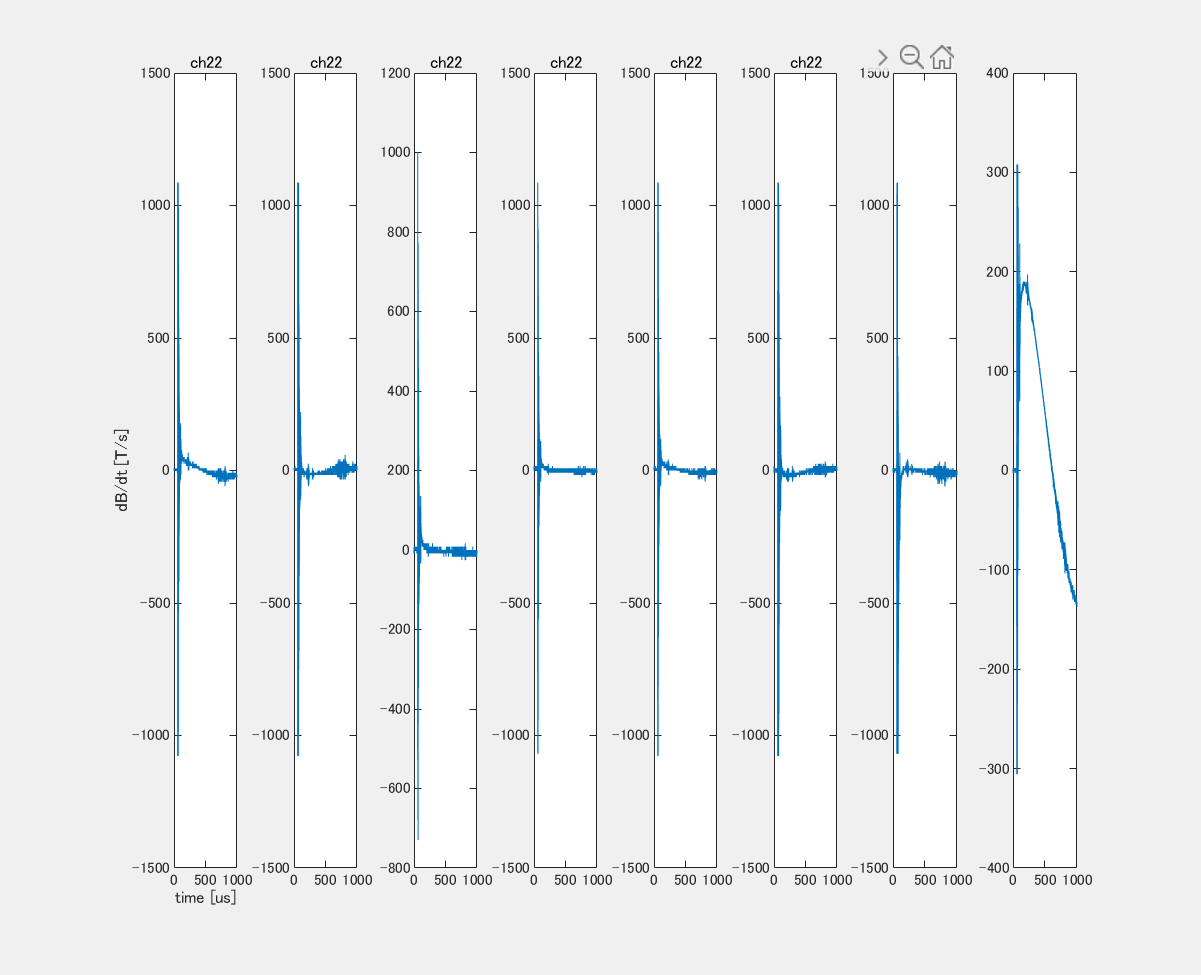

plot_all_ch(M,8);

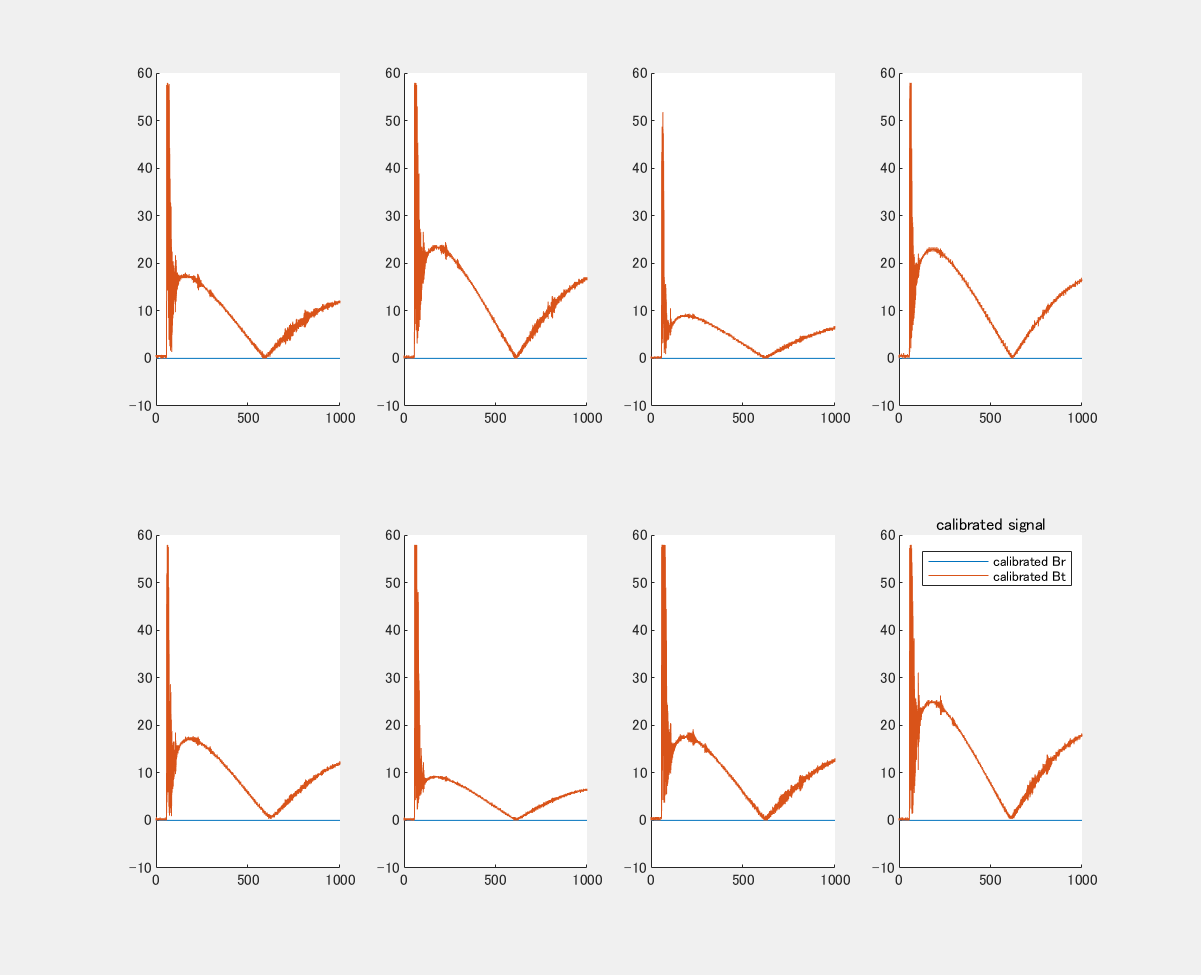


%{
%disp(t);
[calib_bt1, calib_br1] = angle_calibration(t, raw_bt1_2, raw_br1_1);


figure('Position', [0 0 800 800],'visible','on');
hold on;

%raw signal
subplot(2,1,1)
hold on;
plot(t, raw_br1_1);
plot(t, raw_bt1_2);
legend('raw Br1','raw Bt1');   
hold off;
%calibrated signal
subplot(2,1,2)
hold on;
plot(t, calib_br1);  
plot(t, calib_bt1);
legend('calibrated Br1','calibrated Bt1');
hold off; 
title('calibrated signal');
hold off
%}

figure('Position', [0 0 800 800],'visible','on');
total_probe_num = 8;

for probe_number = 1:total_probe_num
    
    raw_bz = M(:, probe_number*3-1)*10^3;
    raw_bt = M(:, probe_number*3)*10^3;
    raw_br = M(:, probe_number*3+1)*10^3;
    [calib_bt calib_br]= angle_calibration(t,raw_bt, raw_br);
    
    subplot(2,4,probe_number);

    %calibrated signal
    hold on;
    plot(t, calib_br);  
    plot(t, calib_bt);
    hold off

end
    legend('calibrated Br','calibrated Bt');
    title('calibrated signal');

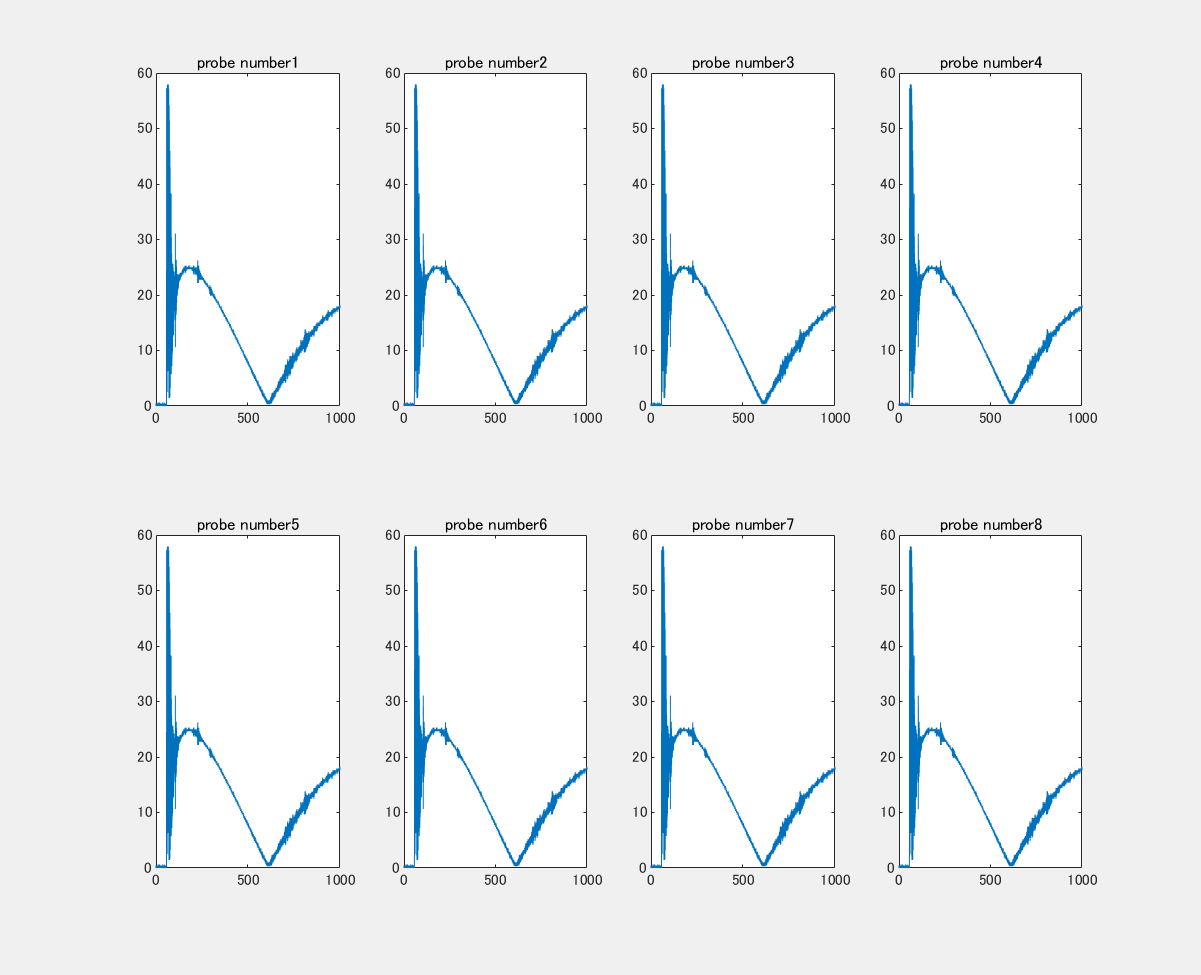

% Br^2 + Bt^2がどのチャンネルでも一緒かどうか

total_probe_num = 8;
Brt = zeros(length(t),total_probe_num);
for probe_number = 1:total_probe_num
NS = [37.7, 41.6, 133]*10^-6;
raw_dbzdt = M(:, probe_number*3-1)/NS(1);
raw_dbtdt = M(:, probe_number*3)/NS(2);
raw_dbrdt = M(:, probe_number*3+1)/NS(3);
Brt(:,probe_number) = sqrt(raw_br.*raw_br + raw_bt.*raw_bt);
end

figure('Position', [0 0 800 800],'visible','on');
for probe_number = 1:total_probe_num
subplot(2,4, probe_number);
plot(t,Brt(:,probe_number));
title(strcat('probe number',' ', num2str(probe_number)));
end

[raw_dbzdt, raw_dbtdt, raw_dbrdt] = plot_each_probe(M, 8);




function [raw_dbzdt, raw_dbtdt, raw_dbrdt] = plot_each_probe(Matrix, total_probe_num)
%(bz, bt, br) = (-1, -2, -3)

%time
t = Matrix(:,1);

%較正係数(NSbz, NSbt, NSbr)
NSztr = [37.7, 41.6,133]*10^-6;

figure('Position', [0 0 800 800],'visible','on');

%dB/dt = - V_coil/NS
for probe_number = 1:total_probe_num
    
    raw_dbzdt = - Matrix(:, probe_number*3-1)/NSztr(1);
    raw_dbtdt = - Matrix(:, probe_number*3)/NSztr(2);
    raw_dbrdt = - Matrix(:, probe_number*3+1)/NSztr(3);

    
    subplot(2,4,probe_number);
    hold on;
    plot(t, raw_dbzdt,'DisplayName','dBz/dt');
    plot(t, raw_dbtdt,'DisplayName','dBt/dt');
    plot(t, raw_dbrdt,'DisplayName','dBr/dt');
    ylim([-500 500]);
    if probe_number == 1
        legend('show');
        xlabel('time [us]');
        ylabel('dB/dt [T/s]');
    end

    title(strcat('probe number',' ',num2str(probe_number)));
    hold off;
end

end




function [raw_dbzdt, raw_dbtdt, raw_dbrdt] = plot_all_ch(Matrix, total_probe_num)
%(bz, bt, br) = (-1, -2, -3)? 

%time
t = Matrix(:,1);

%較正係数(NSbz, NSbt, NSbr)
NSztr = [37.7, 41.6,133]*10^-6;

%dB/dt = - V_coil/NS
raw_dbzdt = zeros(length(t),total_probe_num);
raw_dbtdt = zeros(length(t),total_probe_num);
raw_dbrdt  = zeros(length(t),total_probe_num);
figure('Position', [0 0 800 800],'visible','on');

for probe_number = 1:total_probe_num
    
    raw_dbzdt(:,probe_number) = - Matrix(:, probe_number*3-1)/NSztr(1);
    raw_dbtdt(:,probe_number) = - Matrix(:, probe_number*3)/NSztr(2);
    raw_dbrdt(:,probe_number) = - Matrix(:, probe_number*3+1)/NSztr(3);

end
    
   
    for i  = 1:length(raw_dbzdt(1,:))
     hold on;
     subplot(1,8,i);
     plot(t, raw_dbzdt(:,i));%ch1,4,

    if i == 1
        xlabel('time [us]');
        ylabel('dB/dt [T/s]');
    end

    title(strcat('ch',' ',num2str(probe_number*3-2)));
    hold off;
    end
         plot(t, raw_dbtdt(:,i),'DisplayName','dBt/dt');
     plot(t, raw_dbrdt(:,i),'DisplayName','dBr/dt');
end
